Matlab project :)

**Specific requirements:**

- Introduce the source, format, and background of the data set, what kind of statistical/machine learning task(s) it is originally created for, and websites, papers, or competitions that use the data set.

- Report summary information of the data set, such as #instances, #features (categorical, or numerical), % missing values (if any).

- Visualization of single or small subsets of variables. 

                - Visualization based on 1 - 3 variables at a time should still be performed:

                        - Single categorical variable(s)

                        - Selected single numerical variables

                        - Selected pairs of variables (both numerical, one numerical + one categorical)

                        - Selected triples of variables (all numerical, two numerical + one categorical)

                        - (if we add reviews) Documents data (refer to data_plotting4.m)

- Feature scaling (if the magnitudes of the variables are very different, normalize them to a common range such as [0,1], or [-1,1])

- Dimension reduction methods to be applied to the data set (for simultaneous visualization of all the numerical variables):  

- Linear, unsupervised: PCA

- Linear, supervised: LDA

- Nonlinear, unsupervised, global: MDS (with any metric except Euclidean) 

- Nonlinear, unsupervised, local: Laplacian Eigenmaps, or another nonlinear one (such as LLE). In the latter case, you must provide a brief, clear description of the algorithm regarding how it works.

Project Steps:

- clean the data

- summary statistics, and visualization of single or small subsets of variables. 

- put all numerical data in a matrix and perform feature scaling

- dimension reduction methods

## **Loading the Data**

clear;
opts = delimitedTextImportOptions("NumVariables", 13);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["App", "Category", "Rating", "Reviews", "Size", "Installs", "Type", "Price", "ContentRating", "Genres", "LastUpdated", "CurrentVer", "AndroidVer"];
opts.VariableTypes = ["string", "categorical", "double", "double", "string", "string", "categorical", "string", "categorical", "categorical", "datetime", "string", "string"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, ["App", "Size", "Installs", "Price", "CurrentVer", "AndroidVer"], "WhitespaceRule", "preserve");
opts = setvaropts(opts, ["App", "Category", "Size", "Installs", "Type", "Price", "ContentRating", "Genres", "CurrentVer", "AndroidVer"], "EmptyFieldRule", "auto");
opts = setvaropts(opts, "LastUpdated", "InputFormat", "MMMM d, yyyy");
opts = setvaropts(opts, ["Rating", "Reviews"], "ThousandsSeparator", ",");

% Import the data
data = readtable("data/googleplaystore.csv", opts);
clear opts % clear temporary variables

## **Cleaning the data**

Removing Missing Variables

size(data) % 13 vairables, 10841 apps

ans =        10841          13


Missing data by variable

app = sum(ismissing(data.App));
category = sum(ismissing(data.Category));
rating = sum(ismissing(data.Rating));
reviews = sum(ismissing(data.Reviews));
Size = sum(ismissing(data.Size));
installs = sum(ismissing(data.Installs));
type = sum(ismissing(data.Type));
price = sum(ismissing(data.Price));
contentRating = sum(ismissing(data.ContentRating));
genres = sum(ismissing(data.Genres));
lastUpdated = sum(ismissing(data.LastUpdated));
currentVer = sum(ismissing(data.CurrentVer));
androidVer = sum(ismissing(data.AndroidVer));
table(app, category, rating, reviews, Size, installs, type, price, ...
    contentRating, genres, lastUpdated, currentVer, androidVer)

ans = 1×13 table
    app    category    rating    reviews    Size    installs    type    price    contentRating    genres    lastUpdated    currentVer    androidVer
    ___    ________    ______    _______    ____    ________    ____    _____    _____________    ______    ___________    __________    __________

     0        0         1474        1        0         0         0        0            1            0            1             0             1     


clear Size installs price app rating category reviews type contentRating genres lastUpdated currentVer androidVer;
data( any(ismissing(data),2), :) = [];
size(data)

ans =         9366          13


data(find(string(data.Size)=='Varies with device'),:) = []; % removing weird size
size(data) % size after deleting a ton of variables.

ans =         7729          13


Fixing data types and removing special characters

% data.Sizes
charSize = strtrim(data.Size);
msize = charSize(endsWith(charSize,'M'));
charSize_m = cellstr(string(str2double(string(strrep(msize,'M', '')))*1000));
charSize(endsWith(charSize,'M')) = charSize_m;
SizeOnlyk = strrep(charSize,'k', '');
data.Size_K = SizeOnlyk;
data.Size_K = str2double(string(data.Size_K));
% also add MB data
data.Size_MB = data.Size_K * 0.001

data = 7729×15 table
                            App                                Category       Rating     Reviews       Size       Installs       Type    Price    ContentRating             Genres                 LastUpdated             CurrentVer           AndroidVer      Size_K    Size_MB
    ____________________________________________________    ______________    ______    __________    ______    _____________    ____    _____    _____________    _________________________    __________________    ____________________    


% data.Installs
data.Installs = str2double(strrep(data.Installs,'+',''));

% data.Price
data.Price = str2double(strrep(data.Price,'$',''));

% cleaning up
clear charSize charSize_m msize SizeOnlyk;

## Outliers

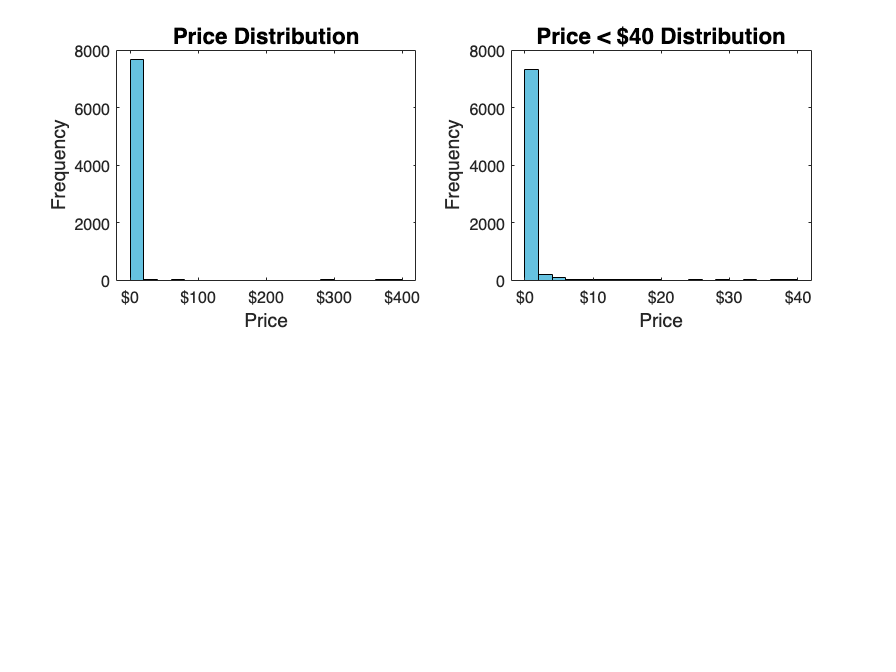

% Price plot
figure;
subplot(2,2,1);
histogram(data.Price,20,FaceColor=[0 153 204]/255)
title("Price Distribution",FontSize=14)
xlabel("Price",FontSize=12)
ylabel("Frequency",FontSize=12)
xtickformat('$%g')
subplot(2,2,2);
histogram(data.Price(find(data.Price<50)),20,FaceColor=[0 153 204]/255)
title("Price < $40 Distribution",FontSize=14)
xlabel("Price",FontSize=12)
ylabel("Frequency",FontSize=12)
xtickformat('$%g')

% saveas(gcf,'figures\price_histogram_outliers.png')
p = sort(data.Price,'descend');
p(1:20)

ans =   400.0000
  399.9900
  399.9900
  399.9900
  399.9900
  399.9900
  399.9900
  399.9900
  399.9900
  399.9900


clear p;

There are 15 apps that are between $399.99 to $299.99 and two apps at $80, the rest are under $40.

We are going to remove the applications that cost over $40.

a = data(find(data.Price > 40),:)

a = 17×15 table
                  App                   Category     Rating    Reviews     Size     Installs    Type    Price     ContentRating       Genres           LastUpdated       CurrentVer      AndroidVer      Size_K    Size_MB
    ________________________________    _________    ______    _______    ______    ________    ____    ______    _____________    _____________    _________________    __________    ______________    ______    _______

    "Vargo Anesthesia Mega App"    

data(find(data.Price > 40),:) = [];

find(data.ContentRating=="Unrated")

ans = 5866

find(data.ContentRating=="Adults only 18+")

ans =          221
        2165


There is one app with a content rating of "unrated" and 2 apps with a rating of "Adults only 18+" they will be removed

data(find(data.ContentRating=="Unrated"),:) = [];
data(find(data.ContentRating=="Adults only 18+"),:) = [];
% must be re categorized for the removed cateogries to disapear
data.ContentRating = categorical(string(data.ContentRating))

data = 7709×15 table
                            App                                Category       Rating     Reviews       Size     Installs    Type    Price    ContentRating             Genres                 LastUpdated             CurrentVer           AndroidVer      Size_K    Size_MB
    ____________________________________________________    ______________    ______    __________    ______    ________    ____    _____    _____________    _________________________    __________________    ____________________    __________

Visualization plan

Summary statistics: (top 5 we create plots for)

- maximum price (top 5)

- average price of paid games

- maximum installs (top 5)

- average installs

- average size

- average rating

- top 5 ratings

- average reviews

- top 5 reviews

% create a color bank
c = [254 221 11;
    255 153 214;
    145 178 46;
    255 149 84;
    0 153 204;
    97 49 155;
    155 52 124;
    204 0 44;
    0 102 58;
    31 68 255];
c = flip(c,1)/255;

c4 = c([1,2,3,6,8,9],:);
c3 = c([6,5,4,9,10,7],:);
c2 = c([6,5,4],:);
cc = [
    255, 89, 94;
    255, 202, 58;
    138, 201, 38;
    25, 130, 196;
    106, 76, 147];
cc = cc/255;
ct = cc([1,5],:);


## Fixing Sub Genre Problem

% Genres have sub categories!!!!!!!!!
size(categories(categorical(string(data.Genres(contains(string(data.Genres),";"))))))

ans =     65     1


size(data.Genres(contains(string(data.Genres),";")))

ans =    417     1


gg = ["";""];
for i = 1:size(data,1)
    if contains(string(data.Genres(i)),";")
        g = strsplit(string(data.Genres(i)),";");
        gg(i,1) = g(1);
    else
        gg(i,1) = string(data.Genres(i));
    end
end

data.Genres = categorical(gg);

% tables being used
Genres = categories(data.Genres);
Count = countcats(data.Genres);
genres_table = table(Genres,Count);
genres_table = sortrows(genres_table,'Count','descend');
Category = categories(data.Category);
Count = countcats(data.Category);
category_table = table(Category,Count);
category_table = sortrows(category_table,'Count','descend');


## Rating and categorical variables

% Most popular cateogires
[n,bin] = hist(data.Category,unique(data.Category));
[~,idx] = sort(-n);
catCounts = n(idx); % The counts for each category sorted
catOrder = bin(idx); % Thier corresponding category sorted
data.Category = categorical(data.Category,catOrder); % categories will be in order of more popular in graph
dataTopCat = data(find(data.Category == catOrder(1) | data.Category == catOrder(2) ...
    | data.Category == catOrder(3) | data.Category == catOrder(4) ...
    | data.Category == catOrder(5) | data.Category == catOrder(6) ...
    | data.Category == catOrder(7) | data.Category == catOrder(8) ...
    | data.Category == catOrder(9) | data.Category == catOrder(10)),:);

% Most popular Genres
[n,bin] = hist(data.Genres,unique(data.Genres));
[~,idx] = sort(-n);
genreCounts = n(idx); % The counts for each category sorted
genreOrder = bin(idx); % Thier corresponding category sorted
data.Genres = categorical(data.Genres,genreOrder); % genres will be in order of more popular in graph
dataTopGenre = data(find(data.Genres == genreOrder(1) | data.Genres == genreOrder(2) ...
    | data.Genres == genreOrder(3) | data.Genres == genreOrder(4) ...
    | data.Genres == genreOrder(5) | data.Genres == genreOrder(6) ...
    | data.Genres == genreOrder(7) | data.Genres == genreOrder(8) ...
    | data.Genres == genreOrder(9) | data.Genres == genreOrder(10)),:);

## Binning the data

genres_bin = [""; ""];
for i = 1:size(data.Genres)
    if ismember(data.Genres(i), genres_table.Genres(1:4))
        genres_bin(i,1) = string(data.Genres(i));
    else
        genres_bin(i,1) = "Other";
    end
end
data.Genres_bin = categorical(genres_bin);

category_bin = [""; ""];
for i = 1:size(data.Category)
    if ismember(data.Category(i), category_table.Category(1:4))
        category_bin(i,1) = string(data.Category(i));
    else
        category_bin(i,1) = "Other";
    end
end
data.Category_bin = categorical(category_bin);

## IMPLEMENT LOG TRANSFORMATION

data.Reviews_log = log(data.Reviews);
data.Size_MB_log = log(data.Size_MB);
data.Installs_log = log(data.Installs);

% need to redo the plots
dataTopCat_log = data(find(data.Category == catOrder(1) | data.Category == catOrder(2) ...
    | data.Category == catOrder(3) | data.Category == catOrder(4) ...
    | data.Category == catOrder(5) | data.Category == catOrder(6) ...
    | data.Category == catOrder(7) | data.Category == catOrder(8) ...
    | data.Category == catOrder(9) | data.Category == catOrder(10)),:);
dataTopGenre_log = data(find(data.Genres == genreOrder(1) | data.Genres == genreOrder(2) ...
    | data.Genres == genreOrder(3) | data.Genres == genreOrder(4) ...
    | data.Genres == genreOrder(5) | data.Genres == genreOrder(6) ...
    | data.Genres == genreOrder(7) | data.Genres == genreOrder(8) ...
    | data.Genres == genreOrder(9) | data.Genres == genreOrder(10)),:);

## Single Numerical Variable Plots

Shayna

### Rating

figure;
% Ratings plot
subplot(2,2,1)
histogram(data.Rating,30,FaceColor=c(6,:))
title("Rating Distribution",FontSize=14)
xlabel("Rating",FontSize=12)
ylabel("Frequency",FontSize=12)
% Ratings plot
subplot(2,2,2)
histogram(log(data.Rating),30,FaceColor=c(6,:))
title("Log(Ratings) Distribution",FontSize=14)
xlabel("Log(Rating)",FontSize=12)
ylabel("Frequency",FontSize=12)
% saveas(gcf,'figures\rating_histogram.png')

This data will not be log transformed

### Reviews

% Reviews plot
subplot(2,2,1)
histogram(data.Reviews,20,FaceColor=c(6,:))
title("Review Distribution",FontSize=14)
xlabel("Reviews",FontSize=12)
ylabel("Frequency",FontSize=12)
% Reviews plot
subplot(2,2,2)
histogram(log(data.Reviews),20,FaceColor=c(6,:))
title("Log(Review) Distribution",FontSize=14)
xlabel("Log(Reviews)",FontSize=12)
ylabel("Frequency",FontSize=12)
% saveas(gcf,'figures\review_histogram.png')

### Size

% Size plot
subplot(2,2,1)
histogram(data.Size_MB,20,FaceColor=c(6,:))
title("Size Distribution",FontSize=14)
xlabel("Size (MB)",FontSize=12)
ylabel("Frequency",FontSize=12)
xtickformat('%g MB')
% Size plot
subplot(2,2,2)
histogram(log(data.Size_MB),20,FaceColor=c(6,:))
title("Log(Size) Distribution",FontSize=14)
xlabel("Log(Size)",FontSize=12)
ylabel("Frequency",FontSize=12)
% saveas(gcf,'figures\size_histogram.png')

### Installs

% Installs plot
subplot(2,2,1);
histogram(data.Installs,20,FaceColor=c(6,:)) 
title("Installations Distribution",FontSize=14)
xlabel("Installations",FontSize=12)
ylabel("Frequency",FontSize=12)
% Installs plot
subplot(2,2,2);
histogram(log(data.Installs),20,FaceColor=c(6,:))
title("Log(Installations) Distribution",FontSize=14)
xlabel("Log(Installations)",FontSize=12)
ylabel("Count",FontSize=12)
% saveas(gcf,'figures\installs_histogram.png')

## Price

% Price plot
figure;
subplot(2,2,1);
histogram(data.Price,20,FaceColor=c(6,:))
title("Price Distribution",FontSize=14)
xlabel("Price",FontSize=12)
ylabel("Frequency",FontSize=12)
xtickformat('$%g')
% Price plot
subplot(2,2,2);
histogram(log(data.Price+1),20,FaceColor=c(6,:))
title("Log(Price) Distribution",FontSize=14)
xlabel("Log(Price)",FontSize=12)
ylabel("Frequency",FontSize=12)
% saveas(gcf,'figures\price_histogram.png')

## Numerical Data Summary Statistics

% Price
mean(data.Price)
mode(data.Price)
median(data.Price)

% Reviews
mean(data.Reviews)
mode(data.Reviews)
median(data.Reviews)

% Installs
mean(data.Installs)
mode(data.Installs)
median(data.Installs)

% Ratings
mean(data.Rating)
mode(data.Rating)
median(data.Rating)

% Size
mean(data.Size_MB)
mode(data.Size_MB)
median(data.Size_MB)

## Single Categorical Variable Plots

Tien

% Type plot
figure;
G1 = groupcounts(data,'Type');
p = pie(G1.Percent);
colormap = (c);
pText = findobj(p,'Type','text');
percentValues = get(pText,'String'); 
txt = {'Free: ', 'Paid: '};
combinedtxt = strcat(txt,percentValues'); 
pText(1).String = combinedtxt(1);
pText(2).String = combinedtxt(2);

patchHand = findobj(p, 'Type', 'Patch'); 
% Set the color of all patches using the nx3 newColors matrix
patchHand(1).FaceColor = c(6,:);
patchHand(2).FaceColor = c(5,:);

title('Percentage of Free and Paid Apps', 'fontsize',16);
% saveas(gcf,'figures\type_pie.png')

% Category word cloud
figure;
wordcloud(data.Category,'Color','blue');
title('Category Wordcloud')
% saveas(gcf,'figures\category_wordcloud.png')

% Category Plot
figure;
Category = categories(data.Category);
Count = countcats(data.Category);
category_table = table(Category,Count);
category_table = sortrows(category_table,'Count','descend');
top10_category = category_table(1:10,:);
figure
b = bar(top10_category .Count,FaceColor=c(6,:));
xticklabels(top10_category .Category);
ylabel('Counts')
xlabel('Category')
grid on
title('Top 10 Category in Google Play Store App', 'fontsize', 18)
% saveas(gcf,'figures\category_bar.png')

figure
subplot(5,5,[1,2,6,7])
histogram(categorical(string(data.Genres(contains(string(data.Category),"GAME")))),'DisplayOrder','descend')
ylabel('Counts')
grid on
title('Genres in GAME Category', 'fontsize', 12)
subplot(5,5,[3,4,8,9])
histogram(categorical(string(data.Genres(contains(string(data.Category),"FAMILY")))),'DisplayOrder','descend')
ylabel('Counts')
xlabel('Genres')
grid on
title({'Genres in','FAMILY Category'}, 'fontsize', 12)
subplot(5,5,[5,10])
histogram(categorical(string(data.Genres(contains(string(data.Category),"TOOLS")))),'DisplayOrder','descend')
ylabel('Counts')
grid on
title({'Genres in', 'TOOLS Category'}, 'fontsize', 12)
% saveas(gcf,'figures\top_3_category_genres_hist.png')

cw = [0,0,50];
for i = 2:size(unique(data.Genres),1)
    cw(i,:) = cw(i-1,:);
    cw(i,2) = cw(i,2)+4;
    cw(i,3) = cw(i,3)+4;
end
cw = cw/255;
cw2 = cw([1:size(unique(data.Category),1)],:);

% genres word cloud
figure;
subplot(2,2,1)
wordcloud(data.Category,'Color',cw2);
title('Cateogry Wordcloud')
subplot(2,2,2)
wordcloud(data.Genres,'Color',cw);
title('Genres Wordcloud')
% saveas(gcf,'figures\genre_category_wordcloud.png')

% Genres plot
figure;
Genres = categories(data.Genres);
Count = countcats(data.Genres);
genres_table = table(Genres,Count);
genres_table = sortrows(genres_table,'Count','descend');
top10_genres = genres_table(1:10,:);
figure
b = bar(top10_genres.Count,FaceColor=c(6,:));
xticklabels(top10_genres.Genres);
ylabel('Counts')
xlabel('Genres')
grid on
title('Top 10 Genres in Google Play Store App', 'fontsize', 18)
% saveas(gcf,'figures\genre_bar.png')

% Genres plot
Genres = categories(data.Genres);
Count = countcats(data.Genres);
genres_table = table(Genres,Count);
genres_table = sortrows(genres_table,'Count','descend');
top10_genres = genres_table(1:10,:);

figure
subplot(1,2,2)
histogram(data.Genres,FaceColor=[0 153 204]/255,DisplayOrder="ascend",Orientation="horizontal");
xlabel('Counts')
ylabel('Genres')
grid on
title('All Genres', 'fontsize', 16)
xlim([0,700])

subplot(1,2,1)
histogram(data.Category,FaceColor=[0 153 204]/255,DisplayOrder="ascend",Orientation="horizontal");
xlabel('Counts')
ylabel('Category')
grid on
title('All Categories', 'fontsize', 16)
%saveas(gcf,'figures\genre_category_bar_all.png')

% getting counts
Genres_bin = categories(data.Genres_bin);
Count = countcats(data.Genres_bin);
genres_bin_table = table(Genres_bin,Count);
genres_bin_table = sortrows(genres_bin_table,'Count','descend');
Category_bin = categories(data.Category_bin);
Count = countcats(data.Category_bin);
category_bin_table = table(Category_bin,Count);
category_bin_table = sortrows(category_bin_table,'Count','descend');

figure
subplot(2,2,2)
b = bar(genres_bin_table.Count,FaceColor=[0 153 204]/255);
ylabel('Counts')
xlabel('Genres')
xticklabels(genres_bin_table.Genres_bin);
grid on
title('Genres in Google Play Store', 'fontsize', 14)
subplot(2,2,1)
b = bar(category_bin_table.Count,FaceColor=[0 153 204]/255);
ylabel('Counts')
xlabel('Categories')
xticklabels(category_bin_table.Category_bin);
grid on
title('Categories in Google Play Store', 'fontsize', 14)
%saveas(gcf,'figures\genre_category_bar_bin.png')

% re-bin the genres
% Genres plot
figure;
Genres = categories(data.Genres);
Count = countcats(data.Genres);
genres_table = table(Genres,Count);
genres_table = sortrows(genres_table,'Count','descend');
top5_genres = genres_table(1:5,:);
figure
b = bar(top5_genres.Count,FaceColor=c(6,:));
xticklabels(top5_genres.Genres);
ylabel('Counts')
xlabel('Genres')
grid on
title('Top 5 Genres in Google Play Store App', 'fontsize', 18)
% saveas(gcf,'figures\genre_bar.png')

% Content Rating Plot
figure;
big_category_count = countcats(data.ContentRating);
category_name = categories(data.ContentRating);
conten_Rating_count = groupcounts(data,'ContentRating');
figure
b = bar(big_category_count,FaceColor=c(6,:));
xticklabels(category_name);
ylabel('Counts')
ylim([0 6800])
xlabel('Content Rating')
grid on
title('Number of the Content Rating', 'fontsize', 18)
xtips = b.XEndPoints;
ytips = b.YEndPoints;
labels = string(round(conten_Rating_count.Percent,2)) + '%';
text(xtips,ytips,labels,'Color','red','fontsize',10,'HorizontalAlignment','center','VerticalAlignment','bottom')
% saveas(gcf,'figures\contentrating_bar.png')

## Selected pairs of variables one numerical + one categorical

Shayna

(N,C): (rating, category) (rating, type) (rating, content rating) (rating, genre), *Review data was so heavily skewed the graphs look bad so I am skipping it!, (Size, category) (Size, type) (Size, content rating) (Size, genre), (price, category) (price, content rating) (price, genre), *Also skipped installs for the same reason

## Rating and categorical variables

% Most popular cateogires
[n,bin] = hist(data.Category,unique(data.Category));
[~,idx] = sort(-n);
catCounts = n(idx); % The counts for each category sorted
catOrder = bin(idx); % Thier corresponding category sorted
data.Category = categorical(data.Category,catOrder); % categories will be in order of more popular in graph
dataTopCat = data(find(data.Category == catOrder(1) | data.Category == catOrder(2) ...
    | data.Category == catOrder(3) | data.Category == catOrder(4) ...
    | data.Category == catOrder(5) | data.Category == catOrder(6) ...
    | data.Category == catOrder(7) | data.Category == catOrder(8) ...
    | data.Category == catOrder(9) | data.Category == catOrder(10)),:);

% Most popular Genres
[n,bin] = hist(data.Genres,unique(data.Genres));
[~,idx] = sort(-n);
genreCounts = n(idx); % The counts for each category sorted
genreOrder = bin(idx); % Thier corresponding category sorted
data.Genres = categorical(data.Genres,genreOrder); % genres will be in order of more popular in graph
dataTopGenre = data(find(data.Genres == genreOrder(1) | data.Genres == genreOrder(2) ...
    | data.Genres == genreOrder(3) | data.Genres == genreOrder(4) ...
    | data.Genres == genreOrder(5) | data.Genres == genreOrder(6) ...
    | data.Genres == genreOrder(7) | data.Genres == genreOrder(8) ...
    | data.Genres == genreOrder(9) | data.Genres == genreOrder(10)),:);

## Grouped Summary Statistics

% By Genre
gen_rating_gs = groupsummary(data(:,["Genres_bin","Rating"]),"Genres_bin",["mean","median","mode","min","max"]);
gen_reviews_gs = groupsummary(data(:,["Genres_bin","Reviews"]),"Genres_bin",["mean","median","mode","min","max"]);
gen_price_gs = groupsummary(data(:,["Genres_bin","Price"]),"Genres_bin",["mean","median","mode","min","max"]);
gen_installs_gs = groupsummary(data(:,["Genres_bin","Installs"]),"Genres_bin",["mean","median","mode","min","max"]);
gen_size_gs = groupsummary(data(:,["Genres_bin","Size_MB"]),"Genres_bin",["mean","median","mode","min","max"]);

% By Category
cat_rating_gs = groupsummary(data(:,["Category","Rating"]),"Category",["mean","median","mode","min","max"]);
cat_reviews_gs = groupsummary(data(:,["Category","Reviews"]),"Category",["mean","median","mode","min","max"]);
cat_price_gs = groupsummary(data(:,["Category","Price"]),"Category",["mean","median","mode","min","max"]);
cat_installs_gs = groupsummary(data(:,["Category","Installs"]),"Category",["mean","median","mode","min","max"]);
cat_size_gs = groupsummary(data(:,["Category","Size_MB"]),"Category",["mean","median","mode","min","max"]);

% By Type
type_rating_gs = groupsummary(data(:,["Type","Rating"]),"Type",["mean","median","mode","min","max"]);
type_reviews_gs = groupsummary(data(:,["Type","Reviews"]),"Type",["mean","median","mode","min","max"]);
type_price_gs = groupsummary(data(:,["Type","Price"]),"Type",["mean","median","mode","min","max"]);
type_installs_gs = groupsummary(data(:,["Type","Installs"]),"Type",["mean","median","mode","min","max"]);
type_size_gs = groupsummary(data(:,["Type","Size_MB"]),"Type",["mean","median","mode","min","max"]);

% By Content Rating
conr_rating_gs = groupsummary(data(:,["ContentRating","Rating"]),"ContentRating",["mean","median","mode","min","max"]);
conr_reviews_gs = groupsummary(data(:,["ContentRating","Reviews"]),"ContentRating",["mean","median","mode","min","max"]);
conr_price_gs = groupsummary(data(:,["ContentRating","Price"]),"ContentRating",["mean","median","mode","min","max"]);
conr_installs_gs = groupsummary(data(:,["ContentRating","Installs"]),"ContentRating",["mean","median","mode","min","max"]);
conr_size_gs = groupsummary(data(:,["ContentRating","Size_MB"]),"ContentRating",["mean","median","mode","min","max"]);

## Rating

figure()

subplot(3,1,1);
boxplot(data.Rating,data.Category_bin,'OutlierSize',4,'Widths',0.7,'Orientation','horizontal')
ylabel("Category",FontSize=12)
a = get(gca,'XTickLabel');  
set(gca,'XTickLabel',a,'fontsize',11)
set(gca, 'YDir','reverse')
h = findobj(gca,'Tag','Box');
for j=1:length(h)
    patch(get(h(j),'XData'),get(h(j),'YData'),cc(j,:),'FaceAlpha',.5);
end
title("Rating Box Plots")

subplot(3,1,2); 
boxplot(data.Rating,data.Type,'Orientation','horizontal')
a = get(gca,'XTickLabel');  
set(gca,'XTickLabel',a,'fontsize',11)
ylabel("Type",FontSize=12)
set(gca, 'YDir','reverse')
h = findobj(gca,'Tag','Box');
for j=1:length(h)
    patch(get(h(j),'XData'),get(h(j),'YData'),ct(j,:),'FaceAlpha',.5);
end

subplot(3,1,3); 
boxplot(data.Rating,data.ContentRating,'Notch','off','Orientation','horizontal')
a = get(gca,'XTickLabel');  
set(gca,'XTickLabel',a,'fontsize',11)
ylabel("Content Rating",FontSize=12)
set(gca, 'YDir','reverse')
h = findobj(gca,'Tag','Box');
for j=1:length(h)
    patch(get(h(j),'XData'),get(h(j),'YData'),cc(j,:),'FaceAlpha',.5);
end
xlabel("Rating")
% saveas(gcf,'figures\rating_grouped_boxplot.png')

## reviews

figure()

subplot(3,1,1);
boxplot(data.Reviews_log,data.Category_bin,'OutlierSize',4,'Widths',0.7,'Orientation','horizontal')
ylabel("Category",FontSize=12)
a = get(gca,'XTickLabel');  
set(gca,'XTickLabel',a,'fontsize',11)
set(gca, 'YDir','reverse')
h = findobj(gca,'Tag','Box');
for j=1:length(h)
    patch(get(h(j),'XData'),get(h(j),'YData'),cc(j,:),'FaceAlpha',.5);
end
title("Log(Reviews) Box Plots")

subplot(3,1,2); 
boxplot(data.Reviews_log,data.Type,'Orientation','horizontal')
a = get(gca,'XTickLabel');  
set(gca,'XTickLabel',a,'fontsize',11)
ylabel("Type",FontSize=12)
set(gca, 'YDir','reverse')
h = findobj(gca,'Tag','Box');
for j=1:length(h)
    patch(get(h(j),'XData'),get(h(j),'YData'),ct(j,:),'FaceAlpha',.5);
end

subplot(3,1,3); 
boxplot(data.Reviews_log,data.ContentRating,'Notch','off','Orientation','horizontal')
a = get(gca,'XTickLabel');  
set(gca,'XTickLabel',a,'fontsize',11)
ylabel("Content Rating",FontSize=12)
set(gca, 'YDir','reverse')
h = findobj(gca,'Tag','Box');
for j=1:length(h)
    patch(get(h(j),'XData'),get(h(j),'YData'),cc(j,:),'FaceAlpha',.5);
end
xlabel("Log(Reviews)")
% saveas(gcf,'figures\reviews_log_grouped_boxplot.png')

## Size

figure()

subplot(3,1,1);
boxplot(data.Size_MB,data.Category_bin,'OutlierSize',4,'Widths',0.7,'Orientation','horizontal')
ylabel("Category",FontSize=12)
a = get(gca,'XTickLabel');  
set(gca,'XTickLabel',a,'fontsize',11)
set(gca, 'YDir','reverse')
h = findobj(gca,'Tag','Box');
for j=1:length(h)
    patch(get(h(j),'XData'),get(h(j),'YData'),cc(j,:),'FaceAlpha',.5);
end
title("Size Box Plots")
xtickformat('%g MB')

subplot(3,1,2); 
boxplot(data.Size_MB,data.Type,'Orientation','horizontal')
a = get(gca,'XTickLabel');  
set(gca,'XTickLabel',a,'fontsize',11)
ylabel("Type",FontSize=12)
set(gca, 'YDir','reverse')
h = findobj(gca,'Tag','Box');
for j=1:length(h)
    patch(get(h(j),'XData'),get(h(j),'YData'),ct(j,:),'FaceAlpha',.5);
end
xtickformat('%g MB')

subplot(3,1,3); 
boxplot(data.Size_MB,data.ContentRating,'Notch','off','Orientation','horizontal')
a = get(gca,'XTickLabel');  
set(gca,'XTickLabel',a,'fontsize',11)
ylabel("Content Rating",FontSize=12)
set(gca, 'YDir','reverse')
h = findobj(gca,'Tag','Box');
for j=1:length(h)
    patch(get(h(j),'XData'),get(h(j),'YData'),cc(j,:),'FaceAlpha',.5);
end
xlabel("Size")
xtickformat('%g MB')
%saveas(gcf,'figures\size_grouped_boxplot.png')

## Installs

figure()

subplot(3,1,1);
boxplot(data.Installs_log,data.Category_bin,'OutlierSize',4,'Widths',0.7,'Orientation','horizontal')
ylabel("Category",FontSize=12)
a = get(gca,'XTickLabel');  
set(gca,'XTickLabel',a,'fontsize',11)
set(gca, 'YDir','reverse')
h = findobj(gca,'Tag','Box');
for j=1:length(h)
    patch(get(h(j),'XData'),get(h(j),'YData'),cc(j,:),'FaceAlpha',.5);
end
title("Log(Installs) Box Plots")

subplot(3,1,2); 
boxplot(data.Installs_log,data.Type,'Orientation','horizontal')
a = get(gca,'XTickLabel');  
set(gca,'XTickLabel',a,'fontsize',11)
ylabel("Type",FontSize=12)
set(gca, 'YDir','reverse')
h = findobj(gca,'Tag','Box');
for j=1:length(h)
    patch(get(h(j),'XData'),get(h(j),'YData'),ct(j,:),'FaceAlpha',.5);
end

subplot(3,1,3); 
boxplot(data.Installs_log,data.ContentRating,'Notch','off','Orientation','horizontal')
a = get(gca,'XTickLabel');  
set(gca,'XTickLabel',a,'fontsize',11)
ylabel("Content Rating",FontSize=12)
set(gca, 'YDir','reverse')
h = findobj(gca,'Tag','Box');
for j=1:length(h)
    patch(get(h(j),'XData'),get(h(j),'YData'),cc(j,:),'FaceAlpha',.5);
end
xlabel("Log(Installs)")
% saveas(gcf,'figures\installs_log_grouped_boxplot.png')

## Price

figure()

subplot(3,1,1);
boxplot(data.Price(find(data.Price>0)),data.Category_bin(find(data.Price>0)),'OutlierSize',4,'Widths',0.7,'Orientation','horizontal')
ylabel("Category",FontSize=12)
a = get(gca,'XTickLabel');  
set(gca,'XTickLabel',a,'fontsize',11)
set(gca, 'YDir','reverse')
h = findobj(gca,'Tag','Box');
for j=1:length(h)
    patch(get(h(j),'XData'),get(h(j),'YData'),cc(j,:),'FaceAlpha',.5);
end
title("Price Box Plots")
xtickformat('usd')

subplot(3,1,2); 
boxplot(data.Price(find(data.Price>0)),data.ContentRating(find(data.Price>0)),'Notch','off','Orientation','horizontal')
a = get(gca,'XTickLabel');  
set(gca,'XTickLabel',a,'fontsize',11)
ylabel("Content Rating",FontSize=12)
set(gca, 'YDir','reverse')
h = findobj(gca,'Tag','Box');
for j=1:length(h)
    patch(get(h(j),'XData'),get(h(j),'YData'),cc(j,:),'FaceAlpha',.5);
end
xlabel("Price")
xtickformat('usd')
%saveas(gcf,'figures\price_grouped_boxplot.png')

% cleaning up
%clear catCounts catOrder dataTopCat dataTopGenre genreCounts genreOrder

Selected triples of variables all numerical (tien)

install = data.Installs/1000000000;
review = data.Reviews/1000000;
%size = data.Size_K/1000;

## IMPLEMENT LOG TRANSFORMATION

data.Reviews_log = log(data.Reviews);
data.Size_MB_log = log(data.Size_MB);
data.Installs_log = log(data.Installs);

% need to redo the plots
dataTopCat_log = data(find(data.Category == catOrder(1) | data.Category == catOrder(2) ...
    | data.Category == catOrder(3) | data.Category == catOrder(4) ...
    | data.Category == catOrder(5) | data.Category == catOrder(6) ...
    | data.Category == catOrder(7) | data.Category == catOrder(8) ...
    | data.Category == catOrder(9) | data.Category == catOrder(10)),:);
dataTopGenre_log = data(find(data.Genres == genreOrder(1) | data.Genres == genreOrder(2) ...
    | data.Genres == genreOrder(3) | data.Genres == genreOrder(4) ...
    | data.Genres == genreOrder(5) | data.Genres == genreOrder(6) ...
    | data.Genres == genreOrder(7) | data.Genres == genreOrder(8) ...
    | data.Genres == genreOrder(9) | data.Genres == genreOrder(10)),:);

figure()
t = tiledlayout(5,5,'TileSpacing','compact');
title(t,"Plot of All Numeric Variables",'FontSize',16,'FontWeight','Bold')

ax(1) = nexttile;
scatter(data.Rating,data.Rating,36,cc(4,:),'filled','MarkerEdgeColor','k', ...
    'MarkerFaceAlpha',.2,'MarkerEdgeAlpha',.2);
xticklabels("")
grid on
ylabel('Rating')

ax(2) = nexttile;
scatter(data.Reviews_log,data.Rating,36,cc(4,:),'filled','MarkerEdgeColor','k', ...
    'MarkerFaceAlpha',.2,'MarkerEdgeAlpha',.2)
yticklabels("")
xticklabels("")
grid on

ax(3) = nexttile;
scatter(data.Price,data.Rating,36,cc(4,:),'filled','MarkerEdgeColor','k', ...
    'MarkerFaceAlpha',.2,'MarkerEdgeAlpha',.2);
yticklabels("")
xticklabels("")
grid on

ax(4) = nexttile;
scatter(data.Installs_log,data.Rating,36,cc(4,:),'filled','MarkerEdgeColor','k', ...
    'MarkerFaceAlpha',.2,'MarkerEdgeAlpha',.2);
yticklabels("")
xticklabels("")
grid on

ax(5) = nexttile;
scatter(data.Size_MB_log,data.Rating,36,cc(4,:),'filled','MarkerEdgeColor','k', ...
    'MarkerFaceAlpha',.2,'MarkerEdgeAlpha',.2);
yticklabels("")
xticklabels("")
grid on

ax(6) = nexttile;
scatter(data.Rating,data.Reviews_log,36,cc(4,:),'filled','MarkerEdgeColor','k', ...
    'MarkerFaceAlpha',.2,'MarkerEdgeAlpha',.2);
ylabel('Log(Reviews)')
xticklabels("")
grid on

ax(7) = nexttile; % changed this plot a little too
scatter(data.Reviews_log,data.Reviews_log,36,cc(4,:),'filled','MarkerEdgeColor','k', ...
    'MarkerFaceAlpha',.2,'MarkerEdgeAlpha',.2);
yticklabels("")
xticklabels("")
grid on

ax(8) = nexttile;
scatter(data.Price,data.Reviews_log,36,cc(4,:),'filled','MarkerEdgeColor','k', ...
    'MarkerFaceAlpha',.2,'MarkerEdgeAlpha',.2);
yticklabels("")
xticklabels("")
grid on

ax(9) = nexttile;
scatter(data.Installs_log,data.Reviews_log,36,cc(4,:),'filled','MarkerEdgeColor','k', ...
    'MarkerFaceAlpha',.2,'MarkerEdgeAlpha',.2);
yticklabels("")
xticklabels("")
grid on

ax(10) = nexttile;
scatter(data.Size_MB_log,data.Reviews_log,36,cc(4,:),'filled','MarkerEdgeColor','k', ...
    'MarkerFaceAlpha',.2,'MarkerEdgeAlpha',.2);
yticklabels("")
xticklabels("")
grid on

ax(11) = nexttile;
scatter(data.Rating,data.Price,36,cc(4,:),'filled','MarkerEdgeColor','k', ...
    'MarkerFaceAlpha',.2,'MarkerEdgeAlpha',.2);
xticklabels("")
grid on
ylabel('Price')
ytickformat('usd');

ax(12) = nexttile; % changed this plot a little too
scatter(data.Reviews_log,data.Price,36,cc(4,:),'filled','MarkerEdgeColor','k', ...
    'MarkerFaceAlpha',.2,'MarkerEdgeAlpha',.2);
yticklabels("")
xticklabels("")
grid on

ax(13) = nexttile;
scatter(data.Price,data.Price,36,cc(4,:),'filled','MarkerEdgeColor','k', ...
    'MarkerFaceAlpha',.2,'MarkerEdgeAlpha',.2);
yticklabels("")
xticklabels("")
grid on

ax(14) = nexttile;
scatter(data.Installs_log,data.Price,36,cc(4,:),'filled','MarkerEdgeColor','k', ...
    'MarkerFaceAlpha',.2,'MarkerEdgeAlpha',.2);
yticklabels("")
xticklabels("")
grid on

ax(15) = nexttile;
scatter(data.Size_MB_log,data.Price,36,cc(4,:),'filled','MarkerEdgeColor','k', ...
    'MarkerFaceAlpha',.2,'MarkerEdgeAlpha',.2);
yticklabels("")
xticklabels("")
grid on

ax(16) = nexttile;
scatter(data.Rating,data.Installs_log,36,cc(4,:),'filled','MarkerEdgeColor','k', ...
    'MarkerFaceAlpha',.2,'MarkerEdgeAlpha',.2);
ylabel('Log(Installs)')
xticklabels("")
grid on

ax(17) = nexttile; % changed this plot a little too
scatter(data.Reviews_log,data.Installs_log,36,cc(4,:),'filled','MarkerEdgeColor','k', ...
    'MarkerFaceAlpha',.2,'MarkerEdgeAlpha',.2);
yticklabels("")
xticklabels("")
grid on

ax(18) = nexttile;
scatter(data.Price,data.Installs_log,36,cc(4,:),'filled','MarkerEdgeColor','k', ...
    'MarkerFaceAlpha',.2,'MarkerEdgeAlpha',.2);
yticklabels("")
xticklabels("")
grid on

ax(19) = nexttile;
scatter(data.Installs_log,data.Installs_log,36,cc(4,:),'filled','MarkerEdgeColor','k', ...
    'MarkerFaceAlpha',.2,'MarkerEdgeAlpha',.2);
yticklabels("")
xticklabels("")
grid on

ax(20) = nexttile;
scatter(data.Size_MB_log,data.Installs_log,36,cc(4,:),'filled','MarkerEdgeColor','k', ...
    'MarkerFaceAlpha',.2,'MarkerEdgeAlpha',.2);
yticklabels("")
xticklabels("")
grid on

ax(21) = nexttile;
scatter(data.Rating,data.Size_MB_log,36,cc(4,:),'filled','MarkerEdgeColor','k', ...
    'MarkerFaceAlpha',.2,'MarkerEdgeAlpha',.2);
ylabel('Log(Size)')
yticklabels("")
grid on
xlabel('Rating')

ax(22) = nexttile; % changed this plot a little too
scatter(data.Reviews_log,data.Size_MB_log,36,cc(4,:),'filled','MarkerEdgeColor','k', ...
    'MarkerFaceAlpha',.2,'MarkerEdgeAlpha',.2);
yticklabels("")
grid on
xlabel('Log(Reviews)')

ax(23) = nexttile;
scatter(data.Price,data.Size_MB_log,36,cc(4,:),'filled','MarkerEdgeColor','k', ...
    'MarkerFaceAlpha',.2,'MarkerEdgeAlpha',.2);
yticklabels("")
grid on
xlabel('Price')
xtickformat('usd');

ax(24) = nexttile;
scatter(data.Installs_log,data.Size_MB_log,36,cc(4,:),'filled','MarkerEdgeColor','k', ...
    'MarkerFaceAlpha',.2,'MarkerEdgeAlpha',.2);
yticklabels("")
grid on
xlabel('Log(Installs)')

ax(25) = nexttile;
scatter(data.Size_MB_log,data.Size_MB_log,36,cc(4,:),'filled','MarkerEdgeColor','k', ...
    'MarkerFaceAlpha',.2,'MarkerEdgeAlpha',.2);
yticklabels("")
grid on
xlabel('Log(Size)')
%saveas(gcf,'figures\2n_all.png')

figure;
scatter(data.Installs_log,data.Price,'filled');
xlabel('Log(Install)')
ylabel('Price')
ytickformat('usd')
title('Installs vs Price','fontsize', 14);

## 3 numeric variables

figure();
subplot(1,2,1)
h = scatter3(data,'Installs_log', 'Reviews_log','Rating','filled','ColorVariable','Rating');
set(h, 'MarkerEdgeAlpha', 0.6, 'MarkerFaceAlpha', 0.3)
zlabel('Rating')
ylabel('Log(Reviews)')
xlabel('Log(Installs)')
title("Rating vs Log(Reviews) vs Log(Installs)", FontSize=14)
subplot(1,2,2)
h = scatter3(data,'Installs_log', 'Reviews_log','Rating','filled','ColorVariable','Rating');
set(h, 'MarkerEdgeAlpha', 0.6, 'MarkerFaceAlpha', 0.3)
view(subplot1,[-37.5 30]);
zlabel('Rating')
ylabel('Log(Reviews)')
xlabel('Log(Installs)')
title("Rating vs Log(Reviews) vs Log(Installs)", FontSize=14)

## Selected triples of variables two numerical + one categorical

Shayna

% for content rating graphs
contentRating = unique(data.ContentRating);
cc = [
    255, 89, 94;
    255, 202, 58;
    138, 201, 38;
    25, 130, 196;
    106, 76, 147];
cc = cc/255;

% For type graphs
type = unique(data.Type);
ct = cc([1,5],:);

% For Categories
cat = unique(dataTopCat.Category_bin);

% For Genres
genre = unique(dataTopGenre.Genres_bin);

% markers
m = 'osd^V><pho';

## Content Rating

% Content Rating Plot with numeric variables
figure()
t = tiledlayout(5,5,'TileSpacing','compact');
title(t,"Applications by Content Rating",'FontSize',16,'FontWeight','Bold')

ax(1) = nexttile;
for i=1:size(contentRating,1)
    scatter(data.Rating(find(data.ContentRating == contentRating(i))), ...
    data.Rating(find(data.ContentRating == contentRating(i))), ...
    36,cc(i,:),m(i),'filled','MarkerEdgeColor',cc(i,:),'MarkerFaceAlpha',0.1, ...
    'MarkerEdgeAlpha',.9,'LineWidth',0.8);
hold on
end
ylabel('Rating')
xticklabels("")
grid on
legend(contentRating)

ax(2) = nexttile;
for i=1:size(contentRating,1)
    scatter(data.Reviews_log(find(data.ContentRating == contentRating(i))), ...
    data.Rating(find(data.ContentRating == contentRating(i))), ...
    36,cc(i,:),m(i),'filled','MarkerEdgeColor',cc(i,:),'MarkerFaceAlpha',0.1, ...
    'MarkerEdgeAlpha',.9,'LineWidth',0.8);
hold on
end
xticklabels("")
yticklabels("")
grid on

ax(3) = nexttile;
for i=1:size(contentRating,1)
    scatter(data.Price(find(data.ContentRating == contentRating(i))), ...
    data.Rating(find(data.ContentRating == contentRating(i))), ...
    36,cc(i,:),m(i),'filled','MarkerEdgeColor',cc(i,:),'MarkerFaceAlpha',0.1, ...
    'MarkerEdgeAlpha',.9,'LineWidth',0.8);
hold on
end
xticklabels("")
yticklabels("")
grid on

ax(4) = nexttile;
for i=1:size(contentRating,1)
    scatter(data.Installs_log(find(data.ContentRating == contentRating(i))), ...
    data.Rating(find(data.ContentRating == contentRating(i))), ...
    36,cc(i,:),m(i),'filled','MarkerEdgeColor',cc(i,:),'MarkerFaceAlpha',0.1, ...
    'MarkerEdgeAlpha',.9,'LineWidth',0.8);
hold on
end
xticklabels("")
yticklabels("")
grid on

ax(5) = nexttile;
for i=1:size(contentRating,1)
    scatter(data.Size_MB_log(find(data.ContentRating == contentRating(i))), ...
    data.Rating(find(data.ContentRating == contentRating(i))), ...
    36,cc(i,:),m(i),'filled','MarkerEdgeColor',cc(i,:),'MarkerFaceAlpha',0.1, ...
    'MarkerEdgeAlpha',.9,'LineWidth',0.8);
hold on
end
xticklabels("")
yticklabels("")
grid on

ax(6) = nexttile;
for i=1:size(contentRating,1)
    scatter(data.Rating(find(data.ContentRating == contentRating(i))), ...
    data.Reviews_log(find(data.ContentRating == contentRating(i))), ...
    36,cc(i,:),m(i),'filled','MarkerEdgeColor',cc(i,:),'MarkerFaceAlpha',0.1, ...
    'MarkerEdgeAlpha',.9,'LineWidth',0.8);
hold on
end
ylabel('Log(Reviews)')
xticklabels("")
grid on

ax(7) = nexttile;
for i=1:size(contentRating,1)
    scatter(data.Reviews_log(find(data.ContentRating == contentRating(i))), ...
    data.Reviews_log(find(data.ContentRating == contentRating(i))), ...
    36,cc(i,:),m(i),'filled','MarkerEdgeColor',cc(i,:),'MarkerFaceAlpha',0.1, ...
    'MarkerEdgeAlpha',.9,'LineWidth',0.8);
hold on
end
xticklabels("")
yticklabels("")
grid on

ax(8) = nexttile;
for i=1:size(contentRating,1)
    scatter(data.Price(find(data.ContentRating == contentRating(i))), ...
    data.Reviews_log(find(data.ContentRating == contentRating(i))), ...
    36,cc(i,:),m(i),'filled','MarkerEdgeColor',cc(i,:),'MarkerFaceAlpha',0.1, ...
    'MarkerEdgeAlpha',.9,'LineWidth',0.8);
hold on
end
xticklabels("")
yticklabels("")
grid on

ax(9) = nexttile;
for i=1:size(contentRating,1)
    scatter(data.Installs_log(find(data.ContentRating == contentRating(i))), ...
    data.Reviews_log(find(data.ContentRating == contentRating(i))), ...
    36,cc(i,:),m(i),'filled','MarkerEdgeColor',cc(i,:),'MarkerFaceAlpha',0.1, ...
    'MarkerEdgeAlpha',.9,'LineWidth',0.8);
hold on
end
xticklabels("")
yticklabels("")
grid on

ax(10) = nexttile;
for i=1:size(contentRating,1)
    scatter(data.Size_MB_log(find(data.ContentRating == contentRating(i))), ...
    data.Reviews_log(find(data.ContentRating == contentRating(i))), ...
    36,cc(i,:),m(i),'filled','MarkerEdgeColor',cc(i,:),'MarkerFaceAlpha',0.1, ...
    'MarkerEdgeAlpha',.9,'LineWidth',0.8);
hold on
end
xticklabels("")
yticklabels("")
grid on

ax(11) = nexttile;
for i=1:size(contentRating,1)
    scatter(data.Rating(find(data.ContentRating == contentRating(i))), ...
    data.Price(find(data.ContentRating == contentRating(i))), ...
    36,cc(i,:),m(i),'filled','MarkerEdgeColor',cc(i,:),'MarkerFaceAlpha',0.1, ...
    'MarkerEdgeAlpha',.9,'LineWidth',0.8);
hold on
end
ylabel('Price')
ytickformat('usd');
xticklabels("")
grid on

ax(12) = nexttile;
for i=1:size(contentRating,1)
    scatter(data.Reviews_log(find(data.ContentRating == contentRating(i))), ...
    data.Price(find(data.ContentRating == contentRating(i))), ...
    36,cc(i,:),m(i),'filled','MarkerEdgeColor',cc(i,:),'MarkerFaceAlpha',0.1, ...
    'MarkerEdgeAlpha',.9,'LineWidth',0.8);
hold on
end
xticklabels("")
yticklabels("")
grid on

ax(13) = nexttile;
for i=1:size(contentRating,1)
    scatter(data.Price(find(data.ContentRating == contentRating(i))), ...
    data.Price(find(data.ContentRating == contentRating(i))), ...
    36,cc(i,:),m(i),'filled','MarkerEdgeColor',cc(i,:),'MarkerFaceAlpha',0.1, ...
    'MarkerEdgeAlpha',.9,'LineWidth',0.8);
hold on
end
xticklabels("")
yticklabels("")
grid on

ax(14) = nexttile;
for i=1:size(contentRating,1)
    scatter(data.Installs_log(find(data.ContentRating == contentRating(i))), ...
    data.Price(find(data.ContentRating == contentRating(i))), ...
    36,cc(i,:),m(i),'filled','MarkerEdgeColor',cc(i,:),'MarkerFaceAlpha',0.1, ...
    'MarkerEdgeAlpha',.9,'LineWidth',0.8);
hold on
end
xticklabels("")
yticklabels("")
grid on

ax(15) = nexttile;
for i=1:size(contentRating,1)
    scatter(data.Size_MB_log(find(data.ContentRating == contentRating(i))), ...
    data.Price(find(data.ContentRating == contentRating(i))), ...
    36,cc(i,:),m(i),'filled','MarkerEdgeColor',cc(i,:),'MarkerFaceAlpha',0.1, ...
    'MarkerEdgeAlpha',.9,'LineWidth',0.8);
hold on
end
xticklabels("")
yticklabels("")
grid on

ax(16) = nexttile;
for i=1:size(contentRating,1)
    scatter(data.Rating(find(data.ContentRating == contentRating(i))), ...
    data.Installs_log(find(data.ContentRating == contentRating(i))), ...
    36,cc(i,:),m(i),'filled','MarkerEdgeColor',cc(i,:),'MarkerFaceAlpha',0.1, ...
    'MarkerEdgeAlpha',.9,'LineWidth',0.8);
hold on
end
ylabel('Log(Installs)')
xticklabels("")
grid on


ax(17) = nexttile;
for i=1:size(contentRating,1)
    scatter(data.Reviews_log(find(data.ContentRating == contentRating(i))), ...
    data.Installs_log(find(data.ContentRating == contentRating(i))), ...
    36,cc(i,:),m(i),'filled','MarkerEdgeColor',cc(i,:),'MarkerFaceAlpha',0.1, ...
    'MarkerEdgeAlpha',.9,'LineWidth',0.8);
hold on
end
xticklabels("")
yticklabels("")
grid on

ax(18) = nexttile;
for i=1:size(contentRating,1)
    scatter(data.Price(find(data.ContentRating == contentRating(i))), ...
    data.Installs_log(find(data.ContentRating == contentRating(i))), ...
    36,cc(i,:),m(i),'filled','MarkerEdgeColor',cc(i,:),'MarkerFaceAlpha',0.1, ...
    'MarkerEdgeAlpha',.9,'LineWidth',0.8);
hold on
end
xticklabels("")
yticklabels("")
grid on

ax(19) = nexttile;
for i=1:size(contentRating,1)
    scatter(data.Installs_log(find(data.ContentRating == contentRating(i))), ...
    data.Installs_log(find(data.ContentRating == contentRating(i))), ...
    36,cc(i,:),m(i),'filled','MarkerEdgeColor',cc(i,:),'MarkerFaceAlpha',0.1, ...
    'MarkerEdgeAlpha',.9,'LineWidth',0.8);
hold on
end
xticklabels("")
yticklabels("")
grid on

ax(20) = nexttile;
for i=1:size(contentRating,1)
    scatter(data.Size_MB_log(find(data.ContentRating == contentRating(i))), ...
    data.Installs_log(find(data.ContentRating == contentRating(i))), ...
    36,cc(i,:),m(i),'filled','MarkerEdgeColor',cc(i,:),'MarkerFaceAlpha',0.1, ...
    'MarkerEdgeAlpha',.9,'LineWidth',0.8);
hold on
end
xticklabels("")
yticklabels("")
grid on

ax(21) = nexttile;
for i=1:size(contentRating,1)
    scatter(data.Rating(find(data.ContentRating == contentRating(i))), ...
    data.Size_MB_log(find(data.ContentRating == contentRating(i))), ...
    36,cc(i,:),m(i),'filled','MarkerEdgeColor',cc(i,:),'MarkerFaceAlpha',0.1, ...
    'MarkerEdgeAlpha',.9,'LineWidth',0.8);
hold on
end
xlabel('Rating')
ylabel('Log(Size)')
grid on

ax(22) = nexttile;
for i=1:size(contentRating,1)
    scatter(data.Reviews_log(find(data.ContentRating == contentRating(i))), ...
    data.Size_MB_log(find(data.ContentRating == contentRating(i))), ...
    36,cc(i,:),m(i),'filled','MarkerEdgeColor',cc(i,:),'MarkerFaceAlpha',0.1, ...
    'MarkerEdgeAlpha',.9,'LineWidth',0.8);
hold on
end
xlabel('Log(Reviews)')
yticklabels("")
grid on

ax(23) = nexttile;
for i=1:size(contentRating,1)
    scatter(data.Price(find(data.ContentRating == contentRating(i))), ...
    data.Size_MB_log(find(data.ContentRating == contentRating(i))), ...
    36,cc(i,:),m(i),'filled','MarkerEdgeColor',cc(i,:),'MarkerFaceAlpha',0.1, ...
    'MarkerEdgeAlpha',.9,'LineWidth',0.8);
hold on
end
xlabel('Price')
xtickformat('usd');
yticklabels("")
grid on

ax(24) = nexttile;
for i=1:size(contentRating,1)
    scatter(data.Installs_log(find(data.ContentRating == contentRating(i))), ...
    data.Size_MB_log(find(data.ContentRating == contentRating(i))), ...
    36,cc(i,:),m(i),'filled','MarkerEdgeColor',cc(i,:),'MarkerFaceAlpha',0.1, ...
    'MarkerEdgeAlpha',.9,'LineWidth',0.8);
hold on
end
xlabel('Log(Installs)')
yticklabels("")
grid on

ax(25) = nexttile;
for i=1:size(contentRating,1)
    scatter(data.Size_MB_log(find(data.ContentRating == contentRating(i))), ...
    data.Size_MB_log(find(data.ContentRating == contentRating(i))), ...
    36,cc(i,:),m(i),'filled','MarkerEdgeColor',cc(i,:),'MarkerFaceAlpha',0.1, ...
    'MarkerEdgeAlpha',.9,'LineWidth',0.8);
hold on
end
xlabel('Log(Size)')
yticklabels("")
grid on

lh =legend(ax(1),'Location','NorthOutside','Orientation','Horizontal','NumColumns',4);
lh.Layout.Tile = 'North'; % <----- relative to tiledlayout
saveas(gcf,'figures\2n_contentrating_all.png')

## Type

% Type Plot with numeric variables
figure()
t = tiledlayout(4,4,'TileSpacing','compact');
title(t,"Applications by Type",'FontSize',16,'FontWeight','Bold')

ax(1) = nexttile;
for i=1:size(type,1)
    scatter(data.Rating(find(data.Type == type(i))), ...
    data.Rating(find(data.Type == type(i))), ...
    36,ct(i,:),m(i),'filled','MarkerEdgeColor',ct(i,:),'MarkerFaceAlpha',0.1, ...
    'MarkerEdgeAlpha',.9,'LineWidth',0.8);
hold on
end
ylabel('Rating')
legend(type)

ax(2) = nexttile;
for i=1:size(type,1)
    scatter(data.Reviews_log(find(data.Type == type(i))), ...
    data.Rating(find(data.Type == type(i))), ...
    36,ct(i,:),m(i),'filled','MarkerEdgeColor',ct(i,:),'MarkerFaceAlpha',0.1, ...
    'MarkerEdgeAlpha',.9,'LineWidth',0.8);
hold on
end

ax(3) = nexttile;
for i=1:size(type,1)
    scatter(data.Price(find(data.Type == type(i))), ...
    data.Rating(find(data.Type == type(i))), ...
    36,ct(i,:),m(i),'filled','MarkerEdgeColor',ct(i,:),'MarkerFaceAlpha',0.1, ...
    'MarkerEdgeAlpha',.9,'LineWidth',0.8);
hold on
end

ax(4) = nexttile;
for i=1:size(type,1)
    scatter(data.Installs_log(find(data.Type == type(i))), ...
    data.Rating(find(data.Type == type(i))), ...
    36,ct(i,:),m(i),'filled','MarkerEdgeColor',ct(i,:),'MarkerFaceAlpha',0.1, ...
    'MarkerEdgeAlpha',.9,'LineWidth',0.8);
hold on
end

ax(5) = nexttile;
for i=1:size(type,1)
    scatter(data.Rating(find(data.Type == type(i))), ...
    data.Reviews_log(find(data.Type == type(i))), ...
    36,ct(i,:),m(i),'filled','MarkerEdgeColor',ct(i,:),'MarkerFaceAlpha',0.1, ...
    'MarkerEdgeAlpha',.9,'LineWidth',0.8);
hold on
end
ylabel('Log(Reviews)')

ax(6) = nexttile;
for i=1:size(type,1)
    scatter(data.Reviews_log(find(data.Type == type(i))), ...
    data.Reviews_log(find(data.Type == type(i))), ...
    36,ct(i,:),m(i),'filled','MarkerEdgeColor',ct(i,:),'MarkerFaceAlpha',0.1, ...
    'MarkerEdgeAlpha',.9,'LineWidth',0.8);
hold on
end

ax(7) = nexttile;
for i=1:size(type,1)
    scatter(data.Price(find(data.Type == type(i))), ...
    data.Reviews_log(find(data.Type == type(i))), ...
    36,ct(i,:),m(i),'filled','MarkerEdgeColor',ct(i,:),'MarkerFaceAlpha',0.1, ...
    'MarkerEdgeAlpha',.9,'LineWidth',0.8);
hold on
end

ax(8) = nexttile;
for i=1:size(type,1)
    scatter(data.Installs_log(find(data.Type == type(i))), ...
    data.Reviews_log(find(data.Type == type(i))), ...
    36,ct(i,:),m(i),'filled','MarkerEdgeColor',ct(i,:),'MarkerFaceAlpha',0.1, ...
    'MarkerEdgeAlpha',.9,'LineWidth',0.8);
hold on
end

ax(9) = nexttile;
for i=1:size(type,1)
    scatter(data.Rating(find(data.Type == type(i))), ...
    data.Price(find(data.Type == type(i))), ...
    36,ct(i,:),m(i),'filled','MarkerEdgeColor',ct(i,:),'MarkerFaceAlpha',0.1, ...
    'MarkerEdgeAlpha',.9,'LineWidth',0.8);
hold on
end
ylabel('Price')
ytickformat('usd');

ax(10) = nexttile;
for i=1:size(type,1)
    scatter(data.Reviews_log(find(data.Type == type(i))), ...
    data.Price(find(data.Type == type(i))), ...
    36,ct(i,:),m(i),'filled','MarkerEdgeColor',ct(i,:),'MarkerFaceAlpha',0.1, ...
    'MarkerEdgeAlpha',.9,'LineWidth',0.8);
hold on
end

ax(11) = nexttile;
for i=1:size(type,1)
    scatter(data.Price(find(data.Type == type(i))), ...
    data.Price(find(data.Type == type(i))), ...
    36,ct(i,:),m(i),'filled','MarkerEdgeColor',ct(i,:),'MarkerFaceAlpha',0.1, ...
    'MarkerEdgeAlpha',.9,'LineWidth',0.8);
hold on
end

ax(12) = nexttile;
for i=1:size(type,1)
    scatter(data.Installs_log(find(data.Type == type(i))), ...
    data.Price(find(data.Type == type(i))), ...
    36,ct(i,:),m(i),'filled','MarkerEdgeColor',ct(i,:),'MarkerFaceAlpha',0.1, ...
    'MarkerEdgeAlpha',.9,'LineWidth',0.8);
hold on
end

ax(13) = nexttile;
for i=1:size(type,1)
    scatter(data.Rating(find(data.Type == type(i))), ...
    data.Installs_log(find(data.Type == type(i))), ...
    36,ct(i,:),m(i),'filled','MarkerEdgeColor',ct(i,:),'MarkerFaceAlpha',0.1, ...
    'MarkerEdgeAlpha',.9,'LineWidth',0.8);
hold on
end
xlabel('Rating')
ylabel('Log(Installs)')

ax(14) = nexttile;
for i=1:size(type,1)
    scatter(data.Reviews_log(find(data.Type == type(i))), ...
    data.Installs_log(find(data.Type == type(i))), ...
    36,ct(i,:),m(i),'filled','MarkerEdgeColor',ct(i,:),'MarkerFaceAlpha',0.1, ...
    'MarkerEdgeAlpha',.9,'LineWidth',0.8);
hold on
end
xlabel('Log(Reviews)')

ax(15) = nexttile;
for i=1:size(type,1)
    scatter(data.Price(find(data.Type == type(i))), ...
    data.Installs_log(find(data.Type == type(i))), ...
    36,ct(i,:),m(i),'filled','MarkerEdgeColor',ct(i,:),'MarkerFaceAlpha',0.1, ...
    'MarkerEdgeAlpha',.9,'LineWidth',0.8);
hold on
end
xlabel('Price')
xtickformat('usd');

ax(16) = nexttile;
for i=1:size(type,1)
    scatter(data.Installs_log(find(data.Type == type(i))), ...
    data.Installs_log(find(data.Type == type(i))), ...
    36,ct(i,:),m(i),'filled','MarkerEdgeColor',ct(i,:),'MarkerFaceAlpha',0.1, ...
    'MarkerEdgeAlpha',.9,'LineWidth',0.8);
hold on
end
xlabel('Log(Installs)')

lh =legend(ax(1),'Location','NorthOutside','Orientation','Horizontal','NumColumns',2);
lh.Layout.Tile = 'North'; % <----- relative to tiledlayout
% saveas(gcf,'figures\2n_type_all.png')

## Category

% Category Plot with numeric variables
c =cc;
figure()
t = tiledlayout(4,4,'TileSpacing','compact');
title(t,"Applications by Category",'FontSize',16,'FontWeight','Bold')

ax(1) = nexttile;
for i=1:size(cat,1)
    scatter(data.Rating(find(data.Category_bin == cat(i))), ...
    data.Rating(find(data.Category_bin == cat(i))), ...
    36,c(i,:),m(i),'filled','MarkerEdgeColor',c(i,:),'MarkerFaceAlpha',0.1, ...
    'MarkerEdgeAlpha',.9,'LineWidth',0.8);
hold on
end
ylabel('Rating')
legend(cat)

ax(2) = nexttile;
for i=1:size(cat,1)
    scatter(data.Reviews_log(find(data.Category_bin == cat(i))), ...
    data.Rating(find(data.Category_bin == cat(i))), ...
    36,c(i,:),m(i),'filled','MarkerEdgeColor',c(i,:),'MarkerFaceAlpha',0.1, ...
    'MarkerEdgeAlpha',.9,'LineWidth',0.8);
hold on
end

ax(3) = nexttile;
for i=1:size(cat,1)
    scatter(data.Price(find(data.Category_bin == cat(i))), ...
    data.Rating(find(data.Category_bin == cat(i))), ...
    36,c(i,:),m(i),'filled','MarkerEdgeColor',c(i,:),'MarkerFaceAlpha',0.1, ...
    'MarkerEdgeAlpha',.9,'LineWidth',0.8);
hold on
end

ax(4) = nexttile;
for i=1:size(cat,1)
    scatter(data.Installs_log(find(data.Category_bin == cat(i))), ...
    data.Rating(find(data.Category_bin == cat(i))), ...
    36,c(i,:),m(i),'filled','MarkerEdgeColor',c(i,:),'MarkerFaceAlpha',0.1, ...
    'MarkerEdgeAlpha',.9,'LineWidth',0.8);
hold on
end

ax(5) = nexttile;
for i=1:size(cat,1)
    scatter(data.Rating(find(data.Category_bin == cat(i))), ...
    data.Reviews_log(find(data.Category_bin == cat(i))), ...
    36,c(i,:),m(i),'filled','MarkerEdgeColor',c(i,:),'MarkerFaceAlpha',0.1, ...
    'MarkerEdgeAlpha',.9,'LineWidth',0.8);
hold on
end
ylabel('Log(Reviews)')

ax(6) = nexttile;
for i=1:size(cat,1)
    scatter(data.Reviews_log(find(data.Category_bin == cat(i))), ...
    data.Reviews_log(find(data.Category_bin == cat(i))), ...
    36,c(i,:),m(i),'filled','MarkerEdgeColor',c(i,:),'MarkerFaceAlpha',0.1, ...
    'MarkerEdgeAlpha',.9,'LineWidth',0.8);
hold on
end

ax(7) = nexttile;
for i=1:size(cat,1)
    scatter(data.Price(find(data.Category_bin == cat(i))), ...
    data.Reviews_log(find(data.Category_bin == cat(i))), ...
    36,c(i,:),m(i),'filled','MarkerEdgeColor',c(i,:),'MarkerFaceAlpha',0.1, ...
    'MarkerEdgeAlpha',.9,'LineWidth',0.8);
hold on
end

ax(8) = nexttile;
for i=1:size(cat,1)
    scatter(data.Installs_log(find(data.Category_bin == cat(i))), ...
    data.Reviews_log(find(data.Category_bin == cat(i))), ...
    36,c(i,:),m(i),'filled','MarkerEdgeColor',c(i,:),'MarkerFaceAlpha',0.1, ...
    'MarkerEdgeAlpha',.9,'LineWidth',0.8);
hold on
end

ax(9) = nexttile;
for i=1:size(cat,1)
    scatter(data.Rating(find(data.Category_bin == cat(i))), ...
    data.Price(find(data.Category_bin == cat(i))), ...
    36,c(i,:),m(i),'filled','MarkerEdgeColor',c(i,:),'MarkerFaceAlpha',0.1, ...
    'MarkerEdgeAlpha',.9,'LineWidth',0.8);
hold on
end
ylabel('Price')
ytickformat('usd');

ax(10) = nexttile;
for i=1:size(cat,1)
    scatter(data.Reviews_log(find(data.Category_bin == cat(i))), ...
    data.Price(find(data.Category_bin == cat(i))), ...
    36,c(i,:),m(i),'filled','MarkerEdgeColor',c(i,:),'MarkerFaceAlpha',0.1, ...
    'MarkerEdgeAlpha',.9,'LineWidth',0.8);
hold on
end

ax(11) = nexttile;
for i=1:size(cat,1)
    scatter(data.Price(find(data.Category_bin == cat(i))), ...
    data.Price(find(data.Category_bin == cat(i))), ...
    36,c(i,:),m(i),'filled','MarkerEdgeColor',c(i,:),'MarkerFaceAlpha',0.1, ...
    'MarkerEdgeAlpha',.9,'LineWidth',0.8);
hold on
end

ax(12) = nexttile;
for i=1:size(cat,1)
    scatter(data.Installs_log(find(data.Category_bin == cat(i))), ...
    data.Price(find(data.Category_bin == cat(i))), ...
    36,c(i,:),m(i),'filled','MarkerEdgeColor',c(i,:),'MarkerFaceAlpha',0.1, ...
    'MarkerEdgeAlpha',.9,'LineWidth',0.8);
hold on
end

ax(13) = nexttile;
for i=1:size(cat,1)
    scatter(data.Rating(find(data.Category_bin == cat(i))), ...
    data.Installs_log(find(data.Category_bin == cat(i))), ...
    36,c(i,:),m(i),'filled','MarkerEdgeColor',c(i,:),'MarkerFaceAlpha',0.1, ...
    'MarkerEdgeAlpha',.9,'LineWidth',0.8);
hold on
end
xlabel('Rating')
ylabel('Log(Installs)')

ax(14) = nexttile;
for i=1:size(cat,1)
    scatter(data.Reviews_log(find(data.Category_bin == cat(i))), ...
    data.Installs_log(find(data.Category_bin == cat(i))), ...
    36,c(i,:),m(i),'filled','MarkerEdgeColor',c(i,:),'MarkerFaceAlpha',0.1, ...
    'MarkerEdgeAlpha',.9,'LineWidth',0.8);
hold on
end
xlabel('Log(Reviews)')

ax(15) = nexttile;
for i=1:size(cat,1)
    scatter(data.Price(find(data.Category_bin == cat(i))), ...
    data.Installs_log(find(data.Category_bin == cat(i))), ...
    36,c(i,:),m(i),'filled','MarkerEdgeColor',c(i,:),'MarkerFaceAlpha',0.1, ...
    'MarkerEdgeAlpha',.9,'LineWidth',0.8);
hold on
end
xlabel('Price')
xtickformat('usd');

ax(16) = nexttile;
for i=1:size(cat,1)
    scatter(data.Installs_log(find(data.Category_bin == cat(i))), ...
    data.Installs_log(find(data.Category_bin == cat(i))), ...
    36,c(i,:),m(i),'filled','MarkerEdgeColor',c(i,:),'MarkerFaceAlpha',0.1, ...
    'MarkerEdgeAlpha',.9,'LineWidth',0.8);
hold on
end
xlabel('Log(Installs)')

lh =legend(ax(1),'Location','NorthOutside','Orientation','Horizontal','NumColumns',5);
lh.Layout.Tile = 'North'; % <----- relative to tiledlayout
saveas(gcf,'figures\2n_category_all.png')

## Genres

% Genres Plot with numeric variables
figure()
t = tiledlayout(4,4,'TileSpacing','compact');
title(t,"Applications by Genres",'FontSize',16,'FontWeight','Bold')

ax(1) = nexttile;
for i=1:size(genre,1)
    scatter(data.Rating(find(data.Genres == genre(i))), ...
    data.Rating(find(data.Genres == genre(i))), ...
    36,c(i,:),m(i),'filled','MarkerEdgeColor',c(i,:),'MarkerFaceAlpha',0.1, ...
    'MarkerEdgeAlpha',.9,'LineWidth',0.8);
hold on
end
ylabel('Rating')
legend(genre)

ax(2) = nexttile;
for i=1:size(genre,1)
    scatter(data.Reviews_log(find(data.Genres == genre(i))), ...
    data.Rating(find(data.Genres == genre(i))), ...
    36,c(i,:),m(i),'filled','MarkerEdgeColor',c(i,:),'MarkerFaceAlpha',0.1, ...
    'MarkerEdgeAlpha',.9,'LineWidth',0.8);
hold on
end

ax(3) = nexttile;
for i=1:size(genre,1)
    scatter(data.Price(find(data.Genres == genre(i))), ...
    data.Rating(find(data.Genres == genre(i))), ...
    36,c(i,:),m(i),'filled','MarkerEdgeColor',c(i,:),'MarkerFaceAlpha',0.1, ...
    'MarkerEdgeAlpha',.9,'LineWidth',0.8);
hold on
end

ax(4) = nexttile;
for i=1:size(genre,1)
    scatter(data.Installs_log(find(data.Genres == genre(i))), ...
    data.Rating(find(data.Genres == genre(i))), ...
    36,c(i,:),m(i),'filled','MarkerEdgeColor',c(i,:),'MarkerFaceAlpha',0.1, ...
    'MarkerEdgeAlpha',.9,'LineWidth',0.8);
hold on
end

ax(5) = nexttile;
for i=1:size(genre,1)
    scatter(data.Rating(find(data.Genres == genre(i))), ...
    data.Reviews_log(find(data.Genres == genre(i))), ...
    36,c(i,:),m(i),'filled','MarkerEdgeColor',c(i,:),'MarkerFaceAlpha',0.1, ...
    'MarkerEdgeAlpha',.9,'LineWidth',0.8);
hold on
end
ylabel('Log(Reviews)')

ax(6) = nexttile;
for i=1:size(genre,1)
    scatter(data.Reviews_log(find(data.Genres == genre(i))), ...
    data.Reviews_log(find(data.Genres == genre(i))), ...
    36,c(i,:),m(i),'filled','MarkerEdgeColor',c(i,:),'MarkerFaceAlpha',0.1, ...
    'MarkerEdgeAlpha',.9,'LineWidth',0.8);
hold on
end

ax(7) = nexttile;
for i=1:size(genre,1)
    scatter(data.Price(find(data.Genres == genre(i))), ...
    data.Reviews_log(find(data.Genres == genre(i))), ...
    36,c(i,:),m(i),'filled','MarkerEdgeColor',c(i,:),'MarkerFaceAlpha',0.1, ...
    'MarkerEdgeAlpha',.9,'LineWidth',0.8);
hold on
end

ax(8) = nexttile;
for i=1:size(genre,1)
    scatter(data.Installs_log(find(data.Genres == genre(i))), ...
    data.Reviews_log(find(data.Genres == genre(i))), ...
    36,c(i,:),m(i),'filled','MarkerEdgeColor',c(i,:),'MarkerFaceAlpha',0.1, ...
    'MarkerEdgeAlpha',.9,'LineWidth',0.8);
hold on
end

ax(9) = nexttile;
for i=1:size(genre,1)
    scatter(data.Rating(find(data.Genres == genre(i))), ...
    data.Price(find(data.Genres == genre(i))), ...
    36,c(i,:),m(i),'filled','MarkerEdgeColor',c(i,:),'MarkerFaceAlpha',0.1, ...
    'MarkerEdgeAlpha',.9,'LineWidth',0.8);
hold on
end
ylabel('Price')
ytickformat('usd');

ax(10) = nexttile;
for i=1:size(genre,1)
    scatter(data.Reviews_log(find(data.Genres == genre(i))), ...
    data.Price(find(data.Genres == genre(i))), ...
    36,c(i,:),m(i),'filled','MarkerEdgeColor',c(i,:),'MarkerFaceAlpha',0.1, ...
    'MarkerEdgeAlpha',.9,'LineWidth',0.8);
hold on
end

ax(11) = nexttile;
for i=1:size(genre,1)
    scatter(data.Price(find(data.Genres == genre(i))), ...
    data.Price(find(data.Genres == genre(i))), ...
    36,c(i,:),m(i),'filled','MarkerEdgeColor',c(i,:),'MarkerFaceAlpha',0.1, ...
    'MarkerEdgeAlpha',.9,'LineWidth',0.8);
hold on
end

ax(12) = nexttile;
for i=1:size(genre,1)
    scatter(data.Installs_log(find(data.Genres == genre(i))), ...
    data.Price(find(data.Genres == genre(i))), ...
    36,c(i,:),m(i),'filled','MarkerEdgeColor',c(i,:),'MarkerFaceAlpha',0.1, ...
    'MarkerEdgeAlpha',.9,'LineWidth',0.8);
hold on
end

ax(13) = nexttile;
for i=1:size(genre,1)
    scatter(data.Rating(find(data.Genres == genre(i))), ...
    data.Installs_log(find(data.Genres == genre(i))), ...
    36,c(i,:),m(i),'filled','MarkerEdgeColor',c(i,:),'MarkerFaceAlpha',0.1, ...
    'MarkerEdgeAlpha',.9,'LineWidth',0.8);
hold on
end
xlabel('Rating')
ylabel('Log(Installs)')

ax(14) = nexttile;
for i=1:size(genre,1)
    scatter(data.Reviews_log(find(data.Genres == genre(i))), ...
    data.Installs_log(find(data.Genres == genre(i))), ...
    36,c(i,:),m(i),'filled','MarkerEdgeColor',c(i,:),'MarkerFaceAlpha',0.1, ...
    'MarkerEdgeAlpha',.9,'LineWidth',0.8);
hold on
end
xlabel('Log(Reviews)')

ax(15) = nexttile;
for i=1:size(genre,1)
    scatter(data.Price(find(data.Genres == genre(i))), ...
    data.Installs_log(find(data.Genres == genre(i))), ...
    36,c(i,:),m(i),'filled','MarkerEdgeColor',c(i,:),'MarkerFaceAlpha',0.1, ...
    'MarkerEdgeAlpha',.9,'LineWidth',0.8);
hold on
end
xlabel('Price')
xtickformat('usd');

ax(16) = nexttile;
for i=1:size(genre,1)
    scatter(data.Installs_log(find(data.Genres == genre(i))), ...
    data.Installs_log(find(data.Genres == genre(i))), ...
    36,c(i,:),m(i),'filled','MarkerEdgeColor',c(i,:),'MarkerFaceAlpha',0.1, ...
    'MarkerEdgeAlpha',.9,'LineWidth',0.8);
hold on
end
xlabel('Log(Installs)')

lh =legend(ax(1),'Location','NorthOutside','Orientation','Horizontal','NumColumns',5);
lh.Layout.Tile = 'North'; % <----- relative to tiledlayout
saveas(gcf,'figures\2n_genre_all.png')

Getting all numerical data in a matrix and standardizing it

rating, reviews, size, price, installs

X = [data.Rating data.Reviews_log data.Size_MB_log data.Price data.Installs_log];
X_s = (X-mean(X,1))./std(X); % standardize X

## PCA

[U, S, V] = svds(X_s);
Y = U .* diag(S)';

% figure;
% semilogy(diag(S),'k')
% title("Singular values")

% figure;
% plot(cumsum(diag(S))/sum(diag(S)),'k')
% title("Cumulitave singular values")


figure;
scatter(Y(:,1),Y(:,2))
title("PCA Plot")
xlabel('U_1')
ylabel('U_2')
% saveas(gcf,'figures\PCA.png')

figure
subplot(2,2,1)
for i=1:size(contentRating,1)
    scatter(Y(find(data.ContentRating == contentRating(i)),1), ...
        Y(find(data.ContentRating == contentRating(i)),2),...
        36,cc(i,:),m(i),'filled','MarkerEdgeColor',cc(i,:),'MarkerFaceAlpha',0.1, ...
        'MarkerEdgeAlpha',.9,'LineWidth',0.8);
    hold on
end
xlabel('U_1')
ylabel('U_2')
legend(contentRating,'Location','NorthOutside','Orientation','Horizontal','NumColumns',2)
title("PCA by Content Rating")

subplot(2,2,2)
for i=1:size(cat,1)
    scatter(Y(find(data.Category_bin == cat(i)),1), ...
        Y(find(data.Category_bin == cat(i)),2),...
        36,cc(i,:),m(i),'filled','MarkerEdgeColor',cc(i,:),'MarkerFaceAlpha',0.1, ...
        'MarkerEdgeAlpha',.9,'LineWidth',0.8);
    hold on
end
xlabel('U_1')
ylabel('U_2')
legend(cat,'Location','NorthOutside','Orientation','Horizontal','NumColumns',3)
title("PCA by Category")

subplot(2,2,[3,4])
for i=1:size(type,1)
    scatter(Y(find(data.Type == type(i)),1), ...
        Y(find(data.Type == type(i)),2),...
        36,cc(i,:),m(i),'filled','MarkerEdgeColor',ct(i,:),'MarkerFaceAlpha',0.1, ...
        'MarkerEdgeAlpha',.9,'LineWidth',0.8);
    hold on
end
xlabel('U_1')
ylabel('U_2')
legend(type,'Location','NorthOutside','Orientation','Horizontal','NumColumns',2)
title("PCA by Type")
%saveas(gcf,'figures\PCA_grouped.png')


figure;
scatter3(Y(:,1),Y(:,2),Y(:,3))
% % saveas(gcf,'figures\PCA_3d.png')

## LDA

% LDA for Data contentrating
[~,Y,y_d] = PCALDA(X_s,data.ContentRating,unique(data.ContentRating));

% LDA Plot
figure()
subplot(2,2,1)
for i=1:size(contentRating,1)
    scatter(Y(data.ContentRating == contentRating(i),1), ...
        Y(data.ContentRating == contentRating(i),2),...
        36,cc(i,:),m(i),'filled','MarkerEdgeColor',cc(i,:),'MarkerFaceAlpha',0.1, ...
        'MarkerEdgeAlpha',.9,'LineWidth',0.8);
    hold on
end
xlabel('U_1')
ylabel('U_2')
legend(contentRating,'Location','NorthOutside','Orientation','Horizontal','NumColumns',2);
title("LDA plot for Content Rating")

% LDA for Top 10 Categories
[~,Y,y_d] = PCALDA(X_s,data.Category_bin,unique(data.Category_bin));

% LDA Plot
subplot(2,2,2)
for i=1:size(cat,1)
    scatter(Y(y_d == cat(i),1), ...
        Y(y_d == cat(i),2),...
        36,c(i,:),m(i),'filled','MarkerEdgeColor',cc(i,:),'MarkerFaceAlpha',0.1, ...
        'MarkerEdgeAlpha',.9,'LineWidth',0.8);
    hold on
end
xlabel('U_1')
ylabel('U_2')
legend(cat,'Location','NorthOutside','Orientation','Horizontal','NumColumns',3);
title("PCA(95%) + LDA plot for Category")

% LDA for Data Type
[~,Y,y_d] = PCALDA(X_s,data.Type,unique(data.Type));

% LDA Plot
subplot(2,2,[3,4])
for i=1:size(type,1)
    scatter(Y(data.Type == type(i),1), ...
        Y(data.Type == type(i),2),...
        36,ct(i,:),m(i),'filled','MarkerEdgeColor',ct(i,:),'MarkerFaceAlpha',0.1, ...
        'MarkerEdgeAlpha',.9,'LineWidth',0.8);
    hold on
end
xlabel('U_1')
ylabel('U_2')
legend(type,'Location','NorthOutside','Orientation','Horizontal','NumColumns',2);
title("PCA(95%) + LDA plot for Type")
% saveas(gcf,'figures\LDA_groups.png')

## MDS

% Finding the distances
Da = squareform(pdist(X_s,'cityblock')); % l1
Db = squareform(pdist(X_s,'hamming')); % l2
Dc = squareform(pdist(X_s,'cosine')); % cosine
Dd = squareform(pdist(X_s,'correlation')); % correlation 

Ya = cmdscale(Da,2);
Yb = cmdscale(Db,2);
Yc = cmdscale(Dc,2);
Yd = cmdscale(Dd,2);

figure;
subplot(2,2,1)
scatter(Ya(:,1),Ya(:,2))
title("L1 distance")

subplot(2,2,2)
scatter(Yb(:,1),Yb(:,2))
title("Hamming distance")

subplot(2,2,3)
scatter(Yc(:,1),Yc(:,2))
title("Cosine distance")

subplot(2,2,4)
scatter(Yd(:,1),Yd(:,2))
title("Correlation distance")
sgtitle("MDS plots")
% saveas(gcf,'figures\MDS.png')

figure
t = tiledlayout(2,2,'TileSpacing','compact');
title(t,"MDS Type",'FontSize',16,'FontWeight','Bold')

ax(1) = nexttile;
for i=1:size(type,1)
    scatter(Ya(data.Type == type(i),1), ...
        Ya(data.Type == type(i),2),...
        36,ct(i,:),m(i),'filled','MarkerEdgeColor',ct(i,:),'MarkerFaceAlpha',0.1, ...
        'MarkerEdgeAlpha',.9,'LineWidth',0.8);
    hold on
end
title("L1 distance")

ax(2) = nexttile;
for i=1:size(type,1)
    scatter(Yb(data.Type == type(i),1), ...
        Yb(data.Type == type(i),2),...
        36,ct(i,:),m(i),'filled','MarkerEdgeColor',ct(i,:),'MarkerFaceAlpha',0.1, ...
        'MarkerEdgeAlpha',.9,'LineWidth',0.8);
    hold on
end
title("Hamming distance")

ax(3) = nexttile;
for i=1:size(type,1)
    scatter(Yc(data.Type == type(i),1), ...
        Yc(data.Type == type(i),2),...
        36,ct(i,:),m(i),'filled','MarkerEdgeColor',ct(i,:),'MarkerFaceAlpha',0.1, ...
        'MarkerEdgeAlpha',.9,'LineWidth',0.8);
    hold on
end
title("Cosine distance")

ax(4) = nexttile;
for i=1:size(type,1)
    scatter(Yd(data.Type == type(i),1), ...
        Yd(data.Type == type(i),2),...
        36,ct(i,:),m(i),'filled','MarkerEdgeColor',ct(i,:),'MarkerFaceAlpha',0.1, ...
        'MarkerEdgeAlpha',.9,'LineWidth',0.8);
    hold on
end
title("Correlation distance")

ax(4).Colormap = lines(256);
lh =legend(type,'Location','NorthOutside','Orientation','Horizontal','NumColumns',3);
lh.Layout.Tile = 'North'; % <----- relative to tiledlayou
% saveas(gcf,'figures\MDS_type.png')

figure
t = tiledlayout(2,2,'TileSpacing','compact');
title(t,"MDS ContentRating",'FontSize',16,'FontWeight','Bold')

ax(1) = nexttile;
for i=1:size(contentRating,1)
    scatter(Ya(find(data.ContentRating == contentRating(i)),1), ...
        Ya(find(data.ContentRating == contentRating(i)),2),...
        36,cc(i,:),m(i),'filled','MarkerEdgeColor',cc(i,:),'MarkerFaceAlpha',0.1, ...
        'MarkerEdgeAlpha',.9,'LineWidth',0.8);
    hold on
end
title("L1 distance")

ax(2) = nexttile;
for i=1:size(contentRating,1)
    scatter(Yb(find(data.ContentRating == contentRating(i)),1), ...
        Yb(find(data.ContentRating == contentRating(i)),2),...
        36,cc(i,:),m(i),'filled','MarkerEdgeColor',cc(i,:),'MarkerFaceAlpha',0.1, ...
        'MarkerEdgeAlpha',.9,'LineWidth',0.8);
    hold on
end
title("Hamming distance")

ax(3) = nexttile;
for i=1:size(contentRating,1)
    scatter(Yc(find(data.ContentRating == contentRating(i)),1), ...
        Yc(find(data.ContentRating == contentRating(i)),2),...
        36,cc(i,:),m(i),'filled','MarkerEdgeColor',cc(i,:),'MarkerFaceAlpha',0.1, ...
        'MarkerEdgeAlpha',.9,'LineWidth',0.8);
    hold on
end
title("Cosine distance")

ax(4) = nexttile;
for i=1:size(contentRating,1)
    scatter(Yd(find(data.ContentRating == contentRating(i)),1), ...
        Yd(find(data.ContentRating == contentRating(i)),2),...
        36,cc(i,:),m(i),'filled','MarkerEdgeColor',cc(i,:),'MarkerFaceAlpha',0.1, ...
        'MarkerEdgeAlpha',.9,'LineWidth',0.8);
    hold on
end
title("Correlation distance")

ax(4).Colormap = lines(256);
lh =legend(contentRating,'Location','NorthOutside','Orientation','Horizontal','NumColumns',2);
lh.Layout.Tile = 'North'; % <----- relative to tiledlayout
% saveas(gcf,'figures\MDS_contentrating.png')

figure
t = tiledlayout(2,2,'TileSpacing','compact');
title(t,"MDS Category",'FontSize',16,'FontWeight','Bold')

ax(1) = nexttile;
for i=1:size(cat,1)
    scatter(Ya(ismember(data.Category, cat(i)),1), ...
        Ya(ismember(data.Category, cat(i)),2),...
        36,c(i,:),m(i),'filled','MarkerEdgeColor',cc(i,:),'MarkerFaceAlpha',0.1, ...
        'MarkerEdgeAlpha',.9,'LineWidth',0.8);
    hold on
end
title("L1 distance")

ax(2) = nexttile;
for i=1:size(cat,1)
    scatter(Yb(ismember(data.Category, cat(i)),1), ...
        Yb(ismember(data.Category, cat(i)),2),...
        36,c(i,:),m(i),'filled','MarkerEdgeColor',cc(i,:),'MarkerFaceAlpha',0.1, ...
        'MarkerEdgeAlpha',.9,'LineWidth',0.8);
    hold on
end
title("Hamming distance")

ax(3) = nexttile;
for i=1:size(cat,1)
    scatter(Yc(ismember(data.Category, cat(i)),1), ...
        Yc(ismember(data.Category, cat(i)),2),...
        36,c(i,:),m(i),'filled','MarkerEdgeColor',cc(i,:),'MarkerFaceAlpha',0.1, ...
        'MarkerEdgeAlpha',.9,'LineWidth',0.8);
    hold on
end
title("Cosine distance")

ax(4) = nexttile;
for i=1:size(cat,1)
    scatter(Yd(ismember(data.Category, cat(i)),1), ...
        Yd(ismember(data.Category, cat(i)),2),...
        36,c(i,:),m(i),'filled','MarkerEdgeColor',cc(i,:),'MarkerFaceAlpha',0.1, ...
        'MarkerEdgeAlpha',.9,'LineWidth',0.8);
    hold on
end
title("Correlation distance")

ax(4).Colormap = lines(256);
lh =legend(cat,'Location','NorthOutside','Orientation','Horizontal','NumColumns',5);
lh.Layout.Tile = 'North'; % <----- relative to tiledlayout
% saveas(gcf,'figures\MDS_category.png')

function [V,Y,y_d] = PCALDA(X,y,d) %input is x and y and a list of unique categorical variables
    x_d = X(ismember(y,d),:);
    y_d = y(ismember(y,d));

    % Perform PCA
    X_cent = x_d - mean(x_d);
    s = svds(X_cent);
    fracs = cumsum(s.^2)/norm(X_cent,"fro")^2;
    k = find(fracs>0.95, 1, "first");
    [U,S] = svds(X_cent,k);
    X_pca = U .* diag(S)';

    % instantiate an empty matrix
    M = [];
    m_d = [];
    n_d = [];
    N = 0;
    for i = size(d,1)
        c = d(i);
        m_dtemp = mean(X_pca(y_d==c,:),1).';
        n_dtemp = sum(y_d==c);
        m_d = [m_d m_dtemp];
        n_d = [n_d n_dtemp];
    end
    % Find the centers of each class
    m = (1/(sum(n_d))).*(sum(n_d.*m_d,2));
    M = sqrt(n_d).*(m_d-m);

    % find sb
    sb = M*M.';
    % Find X tilde for each class
    X_t = X_pca;
    for i=1:size(d,2)
        X_t(y_d==d(i),:) = X_pca(y_d==d(i),:) - m_d(:,i).';
    end

    % find sw
    sw = X_t.' * X_t;

    [V,n] = eigs(sb,sw);
    %V = V./sqrt(sum(v.^2)); % normalize
    Y = X_pca * V;
end